%LOAD DATA 

foldernam = "Evolution - Praful\"

foldernam = "Evolution - Praful\"

filnam = foldernam +  "1_CCRN_1_cat"

filnam = "Evolution - Praful\1_CCRN_1_cat"

model_nam = "1-CCRN-1-cat"

model_nam = "1-CCRN-1-cat"


load(foldernam + 'Data\' + model_nam + '_Ham.mat')
load(foldernam + 'Data\' + model_nam + '_hcnet.mat')

root_arr

$$root\_arr = \left(\begin{array}{cccc} 1 & 0.5000 & 0.2500 & 0.1250\\ 2 & 2 & 2 & 2\\ 1.0500 & 0.5513 & 0.2894 & 0.1519 \end{array}\right)$$

%----straight line initial condition

%number of points in the trajectory
traj_pts = 500;

%List of roots
pos_root_arr = double(root_arr)

pos_root_arr =     1.0000    0.5000    0.2500    0.1250
    2.0000    2.0000    2.0000    2.0000
    1.1500    0.6612    0.3802    0.2186



%start & end point
start_idx = 1; end_idx = 3;

%get straight line initial condition joining the end points
q_IC = straight_line_IC(traj_pts,pos_root_arr,start_idx,end_idx);


%For descent 
traj = q_IC;
Initialize_descender

S_arr = 0.0041

%Initialize Descender by getting a phase space (PS) trajectory from x_ic
Initialize_descender

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


S_arr = 1.5164e-04

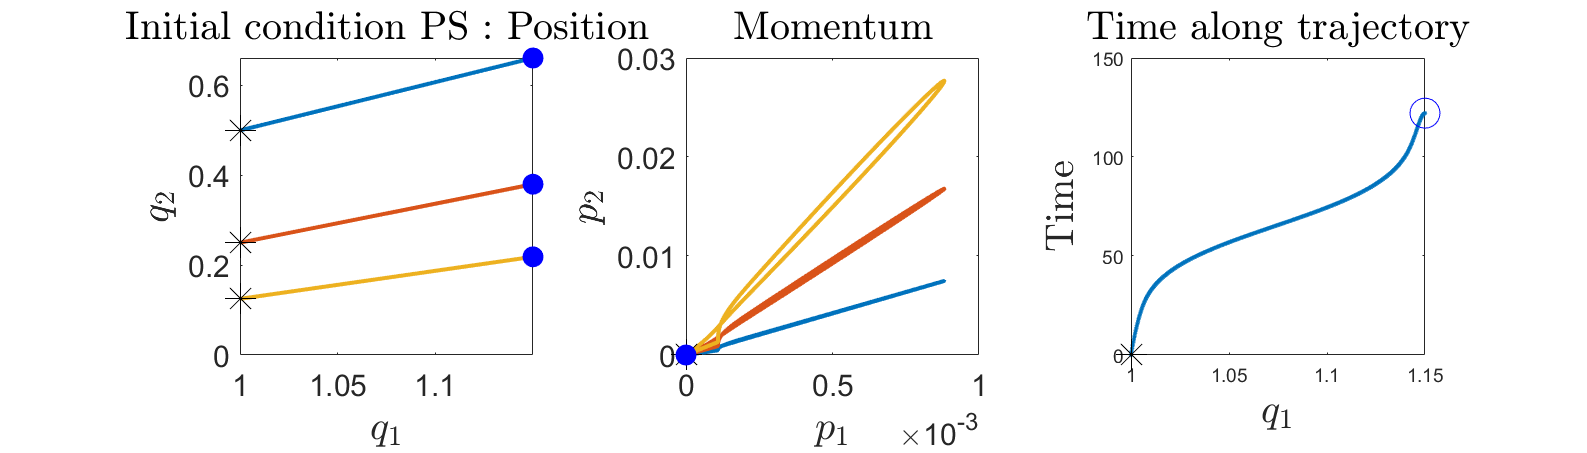

%Plot initial Phase space trajectory
plotnam = "Initial condition PS";
save_plot_name = foldernam + 'Plots\'+model_nam+'_IC_PS_traj.png';
save_plot_flag = 0; %change to 1 to save
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,save_plot_flag)

%Create a .mat file for saving data
savenam = foldernam + 'Data\' + model_nam + '_descend_'+string(start_idx)...
    +'_'+string(end_idx)+'_straightIC_'+string(traj_pts)+'_'+string(date)+'.mat'

savenam = "Evolution - Praful\Data\1-CCRN-1-cat_descend_1_3_straightIC_500_21-Mar-2024.mat"

## Actual descent

%Actual descender parameters

%step size
eps_ic = 1; eps = eps_ic; eps_min = 0.01;    

%Action threshold settings
delta_S = 10; err_thresh = 10^(-1); 
eps_S_thresh = 10^(-7); delta_S_thresh = 10^(-4);
delta_S_thresh_eps = 10^(-4);

%low pass filter settings
f0 = 2; f0_max = 40; f0_step = 0.1; 
time_uniform_f = 45;

%Distance to Hamilton's EoM settings
 a_min=100; a_thresh = 0.001;

%iteration settins
iter_max = 40; iter = 1;

f0 = 5; f0_step = 0.5; delta_S_thresh = 10^(-6);

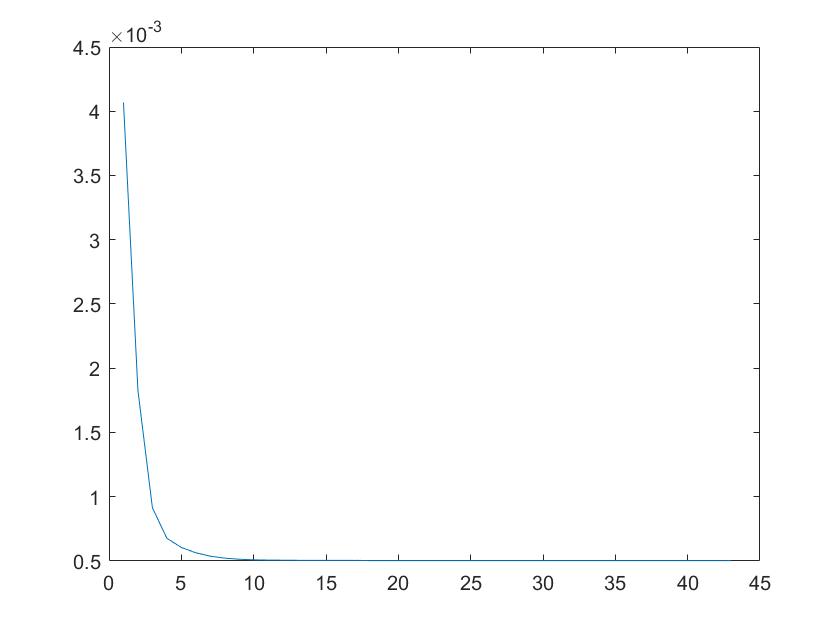

figure()
plot(S_arr)

format long

while f0<f0_max  &&  iter<iter_max && a_min>a_thresh
    iter = iter + 1
    traj_pts = size(traj,1);

    %take a step in the gradient by picking appropriate step size
    [eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
        (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min,delta_S_thresh_eps);
    traj = PS_traj(:,1:num_spec);
    delta_S = action_S_new - action_S;
    [iter, eps, action_S_new, delta_S, f0]
    eps_used = eps;

    
    f0

    if abs(delta_S)<delta_S_thresh || eps < eps_min
        f0 = f0 + 0.1; eps = eps_ic; delta_S = 1;  
        traj = time_uniform_filter(traj,t_traj,traj_pts,time_uniform_f);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    end

    
    %smoothen gradient for next iteration
    delta_x_s =  smooth_traj_butter(delta_x,f0); 

    %Find closest distance by integrating HamEoM
    a_min = ham_closest_approach_noplot(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)

    
    %Update descender and save to file
    Update_descender
    save(savenam)
    
    %Plot some stuff in every some iterations
    %{
    if mod(iter,10)==0
        save_plot_name_root = foldernam + 'Plots\'+model_nam;
        save_plot_name = save_plot_name_root +'_deltax_'+string(iter)+'.png'
        debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,1);
        save_plot_name = save_plot_name_root +'_PS_traj_'+string(iter)+'.png'
        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);
        save_plot_name = save_plot_name_root + '_HamEoM_' + string(iter)+'.png';
        a = ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)
    end
    %}
    
end

iter =     22


delta_S =      2.992621277431683e-06


ans =   22.000000000000000                   0   0.000503152501006                   0   5.000000000000000


f0 =      5


a_min =    0.252646456034699


iter =     23


delta_S =      1.242062418100025e-06


ans =   23.000000000000000                   0   0.000503152501006                   0   5.100000000000000


f0 =    5.100000000000000


a_min =    0.252512422043316


iter =     24


delta_S =      1.847281544090150e-06


ans =   24.000000000000000                   0   0.000503152501006                   0   5.199999999999999


f0 =    5.199999999999999


a_min =    0.252786818395268


iter =     25


delta_S =      1.979974120325245e-06


ans =   25.000000000000000                   0   0.000503152501006                   0   5.299999999999999


f0 =    5.299999999999999


a_min =    0.252895675021975


iter =     26


delta_S =      2.527794889187348e-06


ans =   26.000000000000000                   0   0.000503152501006                   0   5.399999999999999


f0 =    5.399999999999999


a_min =    0.252699334828844


iter =     27


format short

f0_arr

f0_arr =      3
     2
     2
     2
     2
     2
     2
     2
     2
     2


format long
S_arr(end)

ans =      5.031525010062646e-04


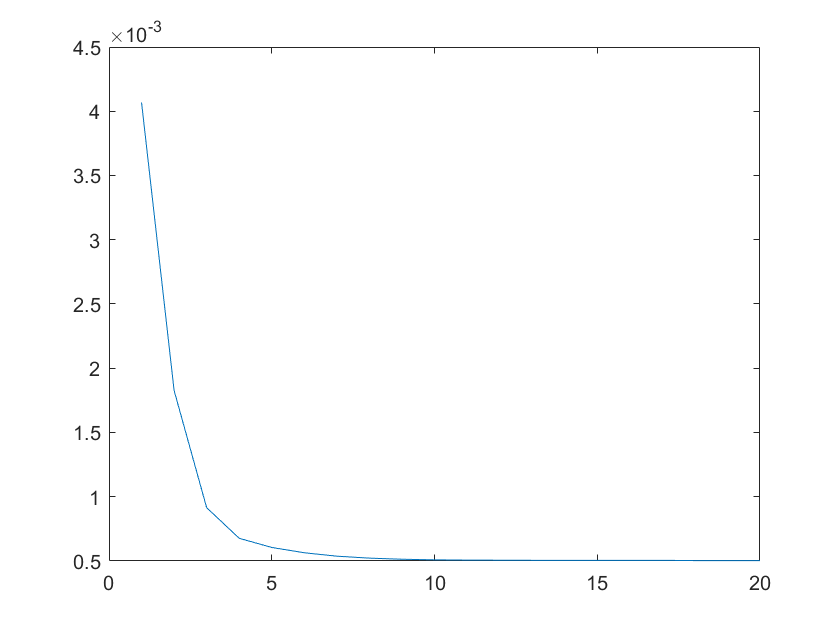

figure()
plot(S_arr)

format long
S_arr(end)

ans =    0.095985990817497


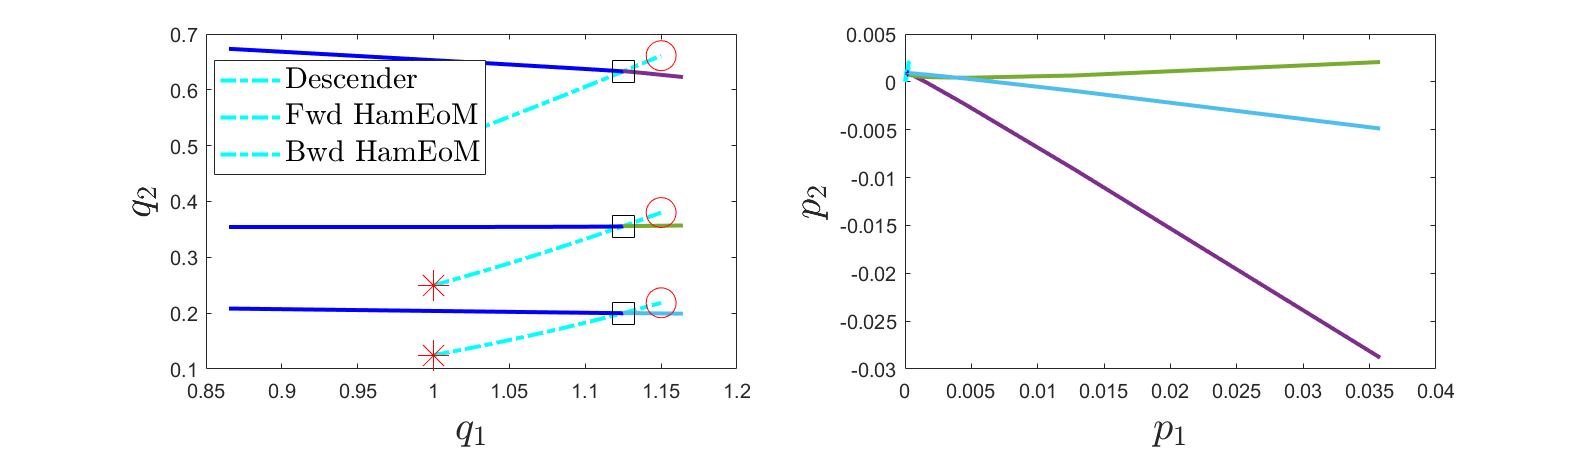

a_min = 0.2449

    a_min = ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)

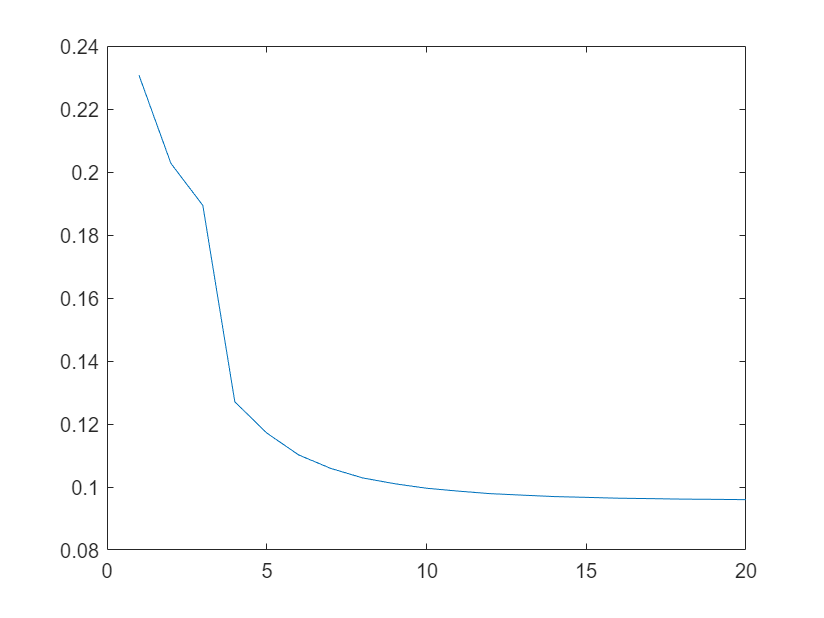

figure()
plot(S_arr)

figure()
plot(S_arr)

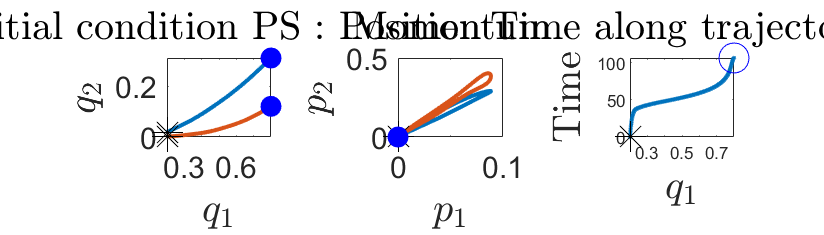

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);

%size(conc_traj)

format long
anneal_ct = 0;
while f0<f0_max  &&  iter<iter_max
    iter = iter + 1;
    traj_pts = size(traj,1);


    %take a step in the gradient by picking appropriate step size
    [eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
        (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,...
        delta_x_s,action_S,eps,num_smooth,eps_min,delta_S_thresh);
    traj = PS_traj(:,1:num_spec);
    delta_S = action_S_new - action_S;
    [iter, eps, action_S_new, delta_S, f0]
    eps_used = eps;
    %if delta_S is positive, then break. If less than threshold then
    %increase cutoff frequency. If descent has stopped, anneal.
    %{
    if delta_S > 0
        disp('Why is action increasing? Error!')
        break
    
    elseif eps == 0
        anneal_ct = anneal_ct + 1;
        f0 = f0 - 0.1; eps = 0.5; delta_S = 1; traj_pts_new = traj_pts;
        if anneal_ct >2
            disp('Annealing')
            traj_pts_new = traj_pts+1000;
            f0 = f0; eps = 1; delta_S = 1;  traj_pts = traj_pts_new;
            anneal_ct = 0;
        end
        traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
        %}
    if f0 > 6
        f0 = f0; eps = 0.5; delta_S = 1; traj_pts_new = traj_pts;
        traj_pts_new = traj_pts+1000;
        traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    

    elseif abs(delta_S)<delta_S_thresh || eps < eps_min
        f0 = f0 + 0.1; eps = 1; delta_S = 1;  
        traj = time_uniform_filter(traj,t_traj,traj_pts,35);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    end

    
    %smoothen gradient for next iteration
    delta_x_s =  smooth_traj_butter(delta_x,f0); 

    
    %Update descender and save to file
    Update_descender
    save(savenam)
    
    %Plot some stuff in every some iterations
    if mod(iter,5)==0
        save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
        +'_'+string(stab_pt_choice)+'_deltax_'+string(iter)+'.png'
        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);
        debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);
    end

    
end

